# example for Multiplicative Extended Kalman Filter (MEKF)

clc
clear
close all

## load true data and add noise

load('qw.mat')

nT = length(t_);
qTrue = q;
wTrue = w;

zyxTrue = q2zyx(4,qTrue);

sigZYX = deg2rad(1e-1); % standard deviation for ZYX euler angles
zyxObs = zyxTrue + sigZYX * randn(nT,3);

qObs = zyx2q(4, zyxObs(:,1), zyxObs(:,2), zyxObs(:,3));


### gyro measurement model

Ru =  1e-10; % 分散
Rnu = 1e-10;  % deg/s
b0 = deg2rad(1e-6 .* ones(nT,3)); % bias initial values, rad/s
bb = b0 + [t_, t_, t_].* deg2rad( sqrt(Rnu) .* randn(nT,3)); % bias
gyroNoise = sqrt(deg2rad(Ru)) .* randn(nT,3);
wObs = wTrue + gyroNoise + bb; % rad/s


## MEKF

### initial estimate

% 初期推定
qGlobal(1,:) = zyx2q(4, randn, randn, randn);

b_hat_minus = [0.0 % bias
    0.0
    0.0];
P_hat_minus = 10 .* eye(6); % error covariance
x_hat_minus = [zeros(3,1) % error quaternionのベクトル部
    b_hat_minus];
oldT = 0;

G = [-1/2.*eye(3) zeros(3,3)
    zeros(3,3) eye(3)]; % システム雑音感度行列

Qu  = eye(3) .* deg2rad(1e-5); % gyroシステム雑音共分散
Qnu = eye(3) .* deg2rad(1e-5); % gyroのbias drift noise
R   = eye(3) .* deg2rad(1e-5); %観測共分散
C = [eye(3) zeros(3,3)]; % 感度行列．quaternionが観測されるとする

xEst(1,:) = zeros(1,6);
P = zeros(6,6,1);
for i = 1:nT-1

    dt   = t_(i+1) - t_(i);
    [qGlobal(i+1,:), xEst(i+1,:),  P(:,:,i+1)] = mekf(dt, xEst(i,:), P(:,:,i), ...
        qGlobal(i,:), qObs(i+1,:), wObs(i+1,:), Qnu, Qu, R);        
end

## show Figs

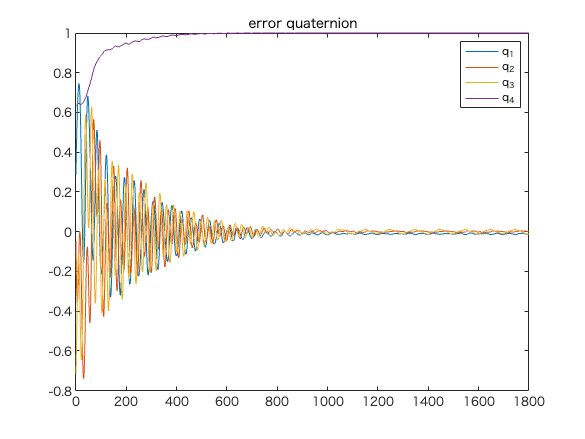


qe = qErr(4, qTrue, qGlobal);


%% error quaternion
figure
plot(t_, qe(:,1), t_, qe(:,2), t_, qe(:,3), t_, qe(:,4));
title('error quaternion')
legend('q_1','q_2','q_3', 'q_4');

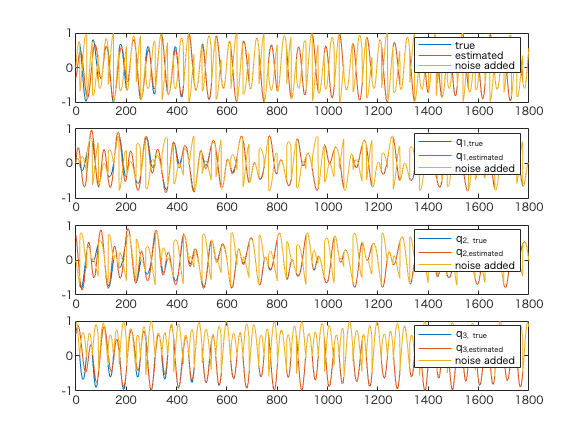


% compare quatrenions
figure
subplot(4,1,1)
plot(t_, qTrue(:,1), t_, qGlobal(:,1), t_, qObs(:,1))
legend('true','estimated', 'noise added')
% xlim([0 30])

subplot(4,1,2)
plot(t_, qTrue(:,2), t_, qGlobal(:,2), t_, qObs(:,2))
legend('q_{1,true}','q_{1,estimated}', 'noise added')
% xlim([0 30])

subplot(4,1,3)
plot(t_, qTrue(:,3), t_, qGlobal(:,3), t_, qObs(:,3))
legend('q_{2, true}','q_{2,estimated}', 'noise added')
% xlim([0 30])

subplot(4,1,4)
plot(t_, qTrue(:,4), t_, qGlobal(:,4), t_, qObs(:,4))
legend('q_{3, true}','q_{3,estimated}', 'noise added')

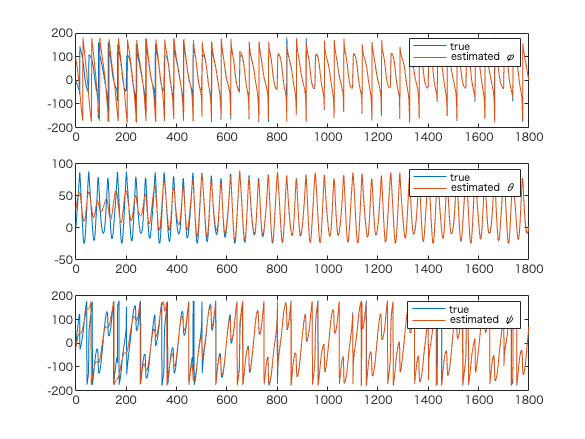

% xlim([0 30])

% ZYX euler angles
zyxTrue = q2zyx(4, qTrue);
zyxEst  = q2zyx(4, qGlobal);

% compare ZYX euler angles
figure
subplot(3,1,1)
plot(t_, rad2deg(zyxTrue(:,1)), t_, rad2deg(zyxEst(:,1)));
legend('true','estimated \phi')

subplot(3,1,2)
plot(t_, rad2deg(zyxTrue(:,2)), t_, rad2deg(zyxEst(:,2)));
legend('true','estimated \theta')

subplot(3,1,3)
plot(t_, rad2deg(zyxTrue(:,3)), t_, rad2deg(zyxEst(:,3)));
legend('true','estimated \psi')



% compare angular rates
% figure
% subplot(3,1,1)
% plot(t_, rad2deg(trueAng(:,1)), t_, rad2deg(wbEst(:,1)), t_, rad2deg(noiseAng(:,1)))
% legend('true','estimated', 'noise added')
% 
% subplot(3,1,2)
% plot(t_, rad2deg(trueAng(:,2)), t_, rad2deg(wbEst(:,2)), t_, rad2deg(noiseAng(:,2)))
% legend('\omega_{y,true}','\omega_{y,estimated}', 'noise added')
% 
% subplot(3,1,3)
% plot(t_, rad2deg(trueAng(:,3)), t_, rad2deg(wbEst(:,3)), t_, rad2deg(noiseAng(:,3)))
% legend('\omega_{z, true}','\omega_{z,estimated}', 'noise added')



% % % error ZYX
% figure
% subplot(3,1,1)
% plot(t_, rad2deg(zyxTrue(:,1)) -  rad2deg(zyxEst(:,1)));
% legend('phi')
% 
% subplot(3,1,2)
% plot(t_, rad2deg(zyxTrue(:,2)) - rad2deg(zyxEst(:,2)));
% legend('theta')
% 
% subplot(3,1,3)
% plot(t_, rad2deg(zyxTrue(:,3)) - rad2deg(zyxEst(:,3)));
% legend('psi')
% 
% % bias estimation error
% figure
% range = 1e-2;
% subplot(3,1,1)
% plot(t_, rad2deg(bb(:,1) - bEst(:,1)))
% legend('b_x');
% ylim([-range range])
% hold on
% plot(t_, 3* rad2deg(P44), 'ro');
% plot(t_, -3* rad2deg(P44), 'ro');
% 
% subplot(3,1,2)
% plot(t_, rad2deg(bb(:,2) - bEst(:,2)))
% legend('b_y');
% ylim([-range range])
% hold on
% plot(t_, 3* rad2deg(P55), 'go');
% plot(t_, -3* rad2deg(P55), 'go');
% 
% subplot(3,1,3);
% plot(t_, rad2deg(bb(:,3) - bEst(:,3)))
% legend('b_z');
% ylim([-range range])
% hold on
% plot(t_, 3* rad2deg(P66), 'bo');
% plot(t_, -3* rad2deg(P66), 'bo');